# Wind

clear;
close all;

load("WeatherData1990_2021")

#### Cut matrix

Use only 08:30 until 17:30 values

horizon_830_1730 = wind.time(:,1) >= 8 & wind.time(:,1) <= 17;

windNames = fields(wind);
windLen = length(fieldnames(wind));
for i = 1:windLen
    sizeTmp = size(wind.(windNames{i}));
    if sizeTmp(2) > 10 %larger than one or greater
        wind.(windNames{i}) = wind.(windNames{i})(:,horizon_830_1730);
    elseif sizeTmp(1) < 500 %for time vectors
        wind.(windNames{i}) = wind.(windNames{i})(horizon_830_1730,:);
    end % if
end % for

additionalNames = fields(additionalData);
additionalLen = length(fieldnames(additionalData));
for i = 1:additionalLen
    sizeTmp = size(additionalData.(additionalNames{i}));
    if sizeTmp(2) > 1 %larger than one or greater
        additionalData.(additionalNames{i}) = additionalData.(additionalNames{i})(:,horizon_830_1730);
    end % if
end % for

#### Wind direction

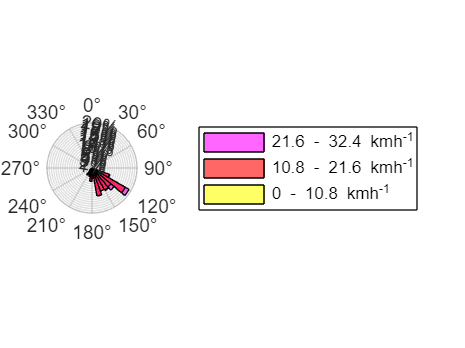

wind1 = 3;
wind2 = 6;
wind3 = 9;

figure
pax = polaraxes;
box on
polarhistogram(deg2rad(additionalData.windDir(wind.windMean<wind3)),deg2rad(0:10:360),'FaceColor','magenta','displayname',[char(num2str(wind2*3.6)),' - ',char(num2str(wind3*3.6)),' kmh^{-1}'])
hold on
polarhistogram(deg2rad(additionalData.windDir(wind.windMean<wind2)),deg2rad(0:10:360),'FaceColor','red','displayname',[char(num2str(wind1*3.6)),' - ',char(num2str(wind2*3.6)),' kmh^{-1}'])
polarhistogram(deg2rad(additionalData.windDir(wind.windMean<wind1)),deg2rad(0:10:360),'FaceColor','yellow','displayname',['0 - ',char(num2str(wind1*3.6)),' kmh^{-1}'])

pax.ThetaDir = 'clockwise';
pax.ThetaZeroLocation = 'top';
clickableLegend
legend('Show','Location','northeast')
% title('Wind rose')

sizeWindSpeed = size(wind.windMean);
numberOfMeasurement = sizeWindSpeed(1)*sizeWindSpeed(2);
maxPerc = 20;
p = 1:maxPerc;
rticks(p/100*numberOfMeasurement)
rticklabels(strcat(string(p),'%'))
rlim([0 maxPerc/100*numberOfMeasurement])

#### Driving direction

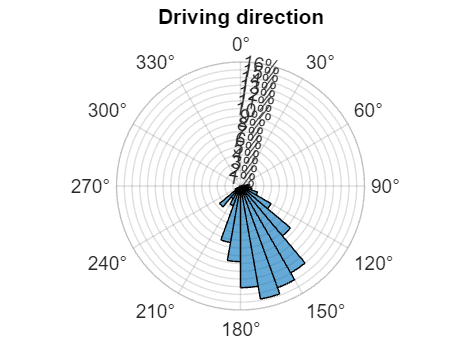

figure
pax = polaraxes;
box on
polarhistogram(deg2rad(additionalData.az),deg2rad(0:10:360))

pax.ThetaDir = 'clockwise';
pax.ThetaZeroLocation = 'top';
title('Driving direction')

sizeDriveDir = size(additionalData.az);
numberOfMeasurement = sizeDriveDir(1)*sizeDriveDir(2);
maxPerc = 16;
p = 1:maxPerc;
rticks(p/100*numberOfMeasurement)
rticklabels(strcat(string(p),'%'))
rlim([0 maxPerc/100*numberOfMeasurement])

#### Side wind and beta angle

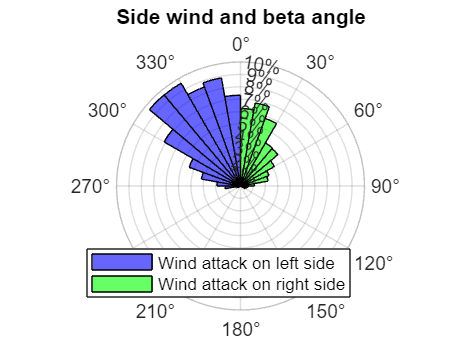

figure
pax = polaraxes;
box on
polarhistogram(-additionalData.beta(additionalData.windAttackOnLeftSide),deg2rad(0:10:360),'FaceColor','blue','displayname','Wind attack on left side')
hold on
polarhistogram(-additionalData.beta(additionalData.windAttackOnRightSide),deg2rad(0:10:360),'FaceColor','green','displayname','Wind attack on right side')

pax.ThetaDir = 'clockwise';
pax.ThetaZeroLocation = 'top';
% clickableLegend
legend('Show','Location','south')
title('Side wind and beta angle')

sizeBeta = size(additionalData.beta);
numberOfMeasurement = sizeBeta(1)*sizeBeta(2);
maxPerc = 10;
p = 1:maxPerc;
rticks(p/100*numberOfMeasurement)
rticklabels(strcat(string(p),'%'))
rlim([0 maxPerc/100*numberOfMeasurement])

#### Front and side wind

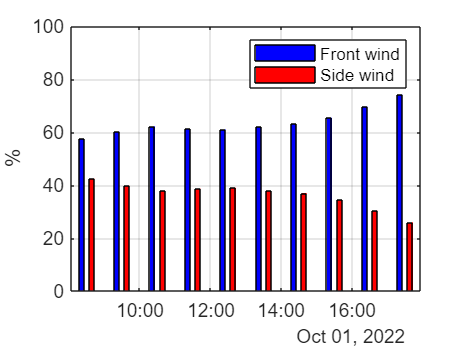

sizeWind = size(wind.sideWind);
distance = 5 * linspace(1,sizeWind(1),sizeWind(1))';

frontWindMean = zeros(sizeWind(2),1);
sideWindMean = zeros(sizeWind(2),1);
frontWindPerc = zeros(sizeWind(2),2);
sideWindPerc = zeros(sizeWind(2),2);

for i = 1:sizeWind(2)
    frontWindMean(i) = mean(wind.frontWind(:,i));
    sideWindMean(i) = mean(wind.sideWind(:,i));
end % for

denom = frontWindMean.^2 + sideWindMean.^2;
frontWindPerc(:,1) = frontWindMean.^2 ./ denom;
sideWindPerc(:,2) = sideWindMean.^2 ./ denom;

Start = datetime(2022,10,1,wind.time(1,1),wind.time(1,2),0, 'Format','HH:mm');
Finish = datetime(2022,10,1,wind.time(end,1),wind.time(end,2),0, 'Format','HH:mm');
Interval = hours(1);
Time = (Start:Interval:Finish).';

figure
bar(Time, frontWindPerc*100, 0.5, 'FaceColor', 'b')
hold on
bar(Time, sideWindPerc*100, 0.5, 'FaceColor', 'r')
legend("Front wind","","Side wind","")
ylabel("%")
ylim([0 100])
grid on

% thisSideWindRight = wind.sideWind;
% thisSideWindLeft = wind.sideWind;
% thisSideWindRight(additionalData.windAttackOnLeftSide) = NaN;
% thisSideWindLeft(additionalData.windAttackOnRightSide) = NaN;
% 
% timeVecHour = hours(5.5) : hours(1) : hours(19.5);
% timeVecHourStr = string(timeVecHour,"hh:mm");
% 
% for i = 1:sizeWind(2)
%     titleName = ['Hour of the day ', char(timeVecHourStr(i)];
%     figure('NumberTitle', 'off', 'Name', titleName);
%     title(titleName)
%     plot(distance, 3.6*wind.frontWind(:,i),'g')
%     hold on
%     plot(distance, 3.6*thisSideWindRight(:,i),'b.-')
%     plot(distance, 3.6*thisSideWindLeft(:,i),'r.-')
%     
%     xlabel("Distance [km]")
%     ylabel("Wind speed [km/h]")
%     legend("Front wind", "Side wind on right side", "Side wind on left side")
%     grid on
%     box on
%     hold off
% end % for